% Code to initialize, estimate parameters and plot simulation results for sscfluids_clutch_ss_primary_cyl

# Single-stage primary cylinder

This example shows how to model, parameterize and test a single-stage primary cylinder starting from manufacturer datasheet information. Given the numerical data extracted from the datasheet, the unknown parameters are calculated. The model is then simulated and the resulting push rod force versus pressure relationship curve is compared with the curve provided on the manufacturer datasheet.

Copyright 2020-21 The MathWorks, Inc.

## Manufacturer datasheet data

% Data reading for the supplier component design parameters

sspc.dp = 31.75*1e-3;               % (m) Piston diameter
sspc.stroke = 36*1e-3;              % (m) Piston stroke
sspc.disp = 27*1e-6;                % (m^3) Circuit displacement
sspc.maxPress = 120*1e5;            % (Pa or N/m^2) Max pressure

% Expected output function diagram
sspc.pushRodF = [0 100 4000];       % (N) Push rod force                     
sspc.circuitP = [0 0   45e5];       % (Pa or N/m^2) Pressure vector

## Pressure development characteristics

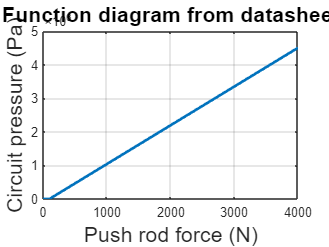

% Plotting the function diagram of single-stage primary cylinder 

p1 = plot(sspc.pushRodF,sspc.circuitP);
p2 = xlabel('Push rod force (N)');
p3 = ylabel('Circuit pressure (Pa)');
p4 = title('Function diagram from datasheet');
grid on
p1.LineWidth = 2;
p2.FontSize = 16;
p3.FontSize = 16;
p4.FontSize = 16;

## Additional assumed and derived parameters 

Some of  the following parameters can be estimated with assumptions.

sspc.aPist = (pi/4)*sspc.dp^2;                              % (m^2) Pressure acting piston area
sspc.deadzone = 1.5e-3;                                     % (m) length for which no pressure generated
sspc.c = 1e-3;                                              % (Ns/m) Damping coefficient
sspc.mass = 1e-2;                                           % (Kg) Piston mass
sspc.v2D = 1000e-9;                                         % (m^3) Circuit dead Volume
sspc.v2M = sspc.v2D+sspc.aPist*(sspc.stroke-sspc.deadzone); % (m^3) Circuit max Volume
sspc.a1Ori = 100e-6;                                        % (m^2) Compensating orifice area
sspc.a2Ori = 10e-6;                                         % (m^2) Circuit orifice area
sspc.pRes = 1e5;                                            % (Pa) Initial Pressure condition
sspc.hss = 1e8;                                             % (N/m) Hard stop stiffness
sspc.hsd = 1e6;                                             % (N/(m/s)) Hard stop damping coefficient 

## Parameter estimation scheme

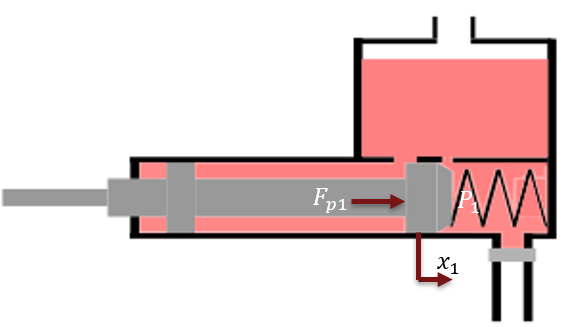

The single-stage primary cylinder is shown in the figure above.

Equation of motion of the system


$$m\overset{\ldotp \ldotp }{x_1 } +\overset{\ldotp }{{\textrm{cx}}_1 } +k_1 x_1 =F_{\textrm{p1}} -P_1 A-{\textrm{Pre}}_L$$


Steady state equation of the system

 
$$k_1 x_1 =F_{\textrm{p1}} -P_1 A-{\textrm{Pre}}_L$$



$$\left\lbrack \begin{array}{cc}
x_{11}  & 1\\
x_{12}  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
k_1 \\
{\textrm{Pre}}_L 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
F_{\textrm{p1}} -P_{11} A\\
F_{\textrm{p2}} -P_{12} A
\end{array}\right\rbrack$$


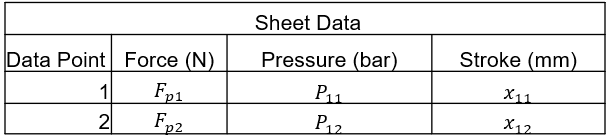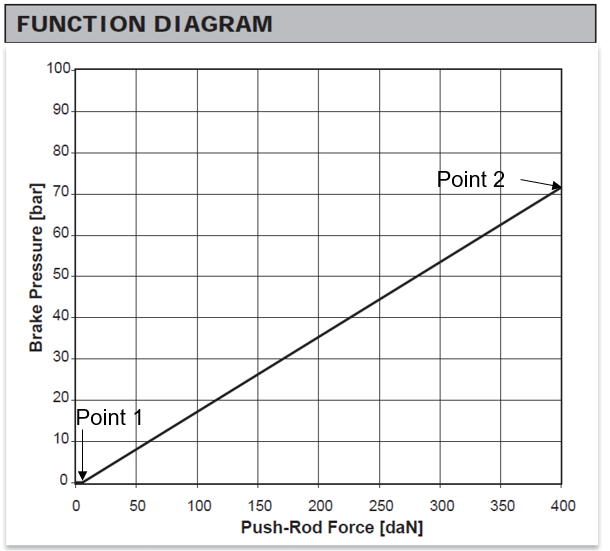

where,

$x_1$ is positions of mass from the left side assumed hard stop.

$m_{\;}$ is mass of piston.

$c$ is damping coefficient of piston.

$k_1$ is spring stiffness coefficients.

$F_{\textrm{P1}} \;$ is force applied on push rod of primary cylinder.

$P_1$ is pressures in brake circuit.

${\textrm{Pre}}_L$ is preloads on spring.

## Parameter estimation

Steady state equation of the system can be solved at 2 points given in the function diagram. Therefore, the parameters governing functionality of the system can be estimated.

sspc.fP1 = sspc.pushRodF(2);
sspc.fP2 = sspc.pushRodF(3);
sspc.P1 = sspc.circuitP(2);
sspc.P2 = sspc.circuitP(3);
sspc.a = [sspc.deadzone 1; ...
         sspc.stroke   1];
sspc.b = [sspc.fP1 - sspc.P1*sspc.aPist; ...
         sspc.fP2 - sspc.P2*sspc.aPist];     
sspc.out = sspc.a\sspc.b;

sspc.k = sspc.out(1);              % (N/m) Spring stiffness
sspc.preL = sspc.out(2);           % (N) Spring preload force
sspc.def = sspc.preL/sspc.k;       % (m) Spring compression


## Setting up model for simulation

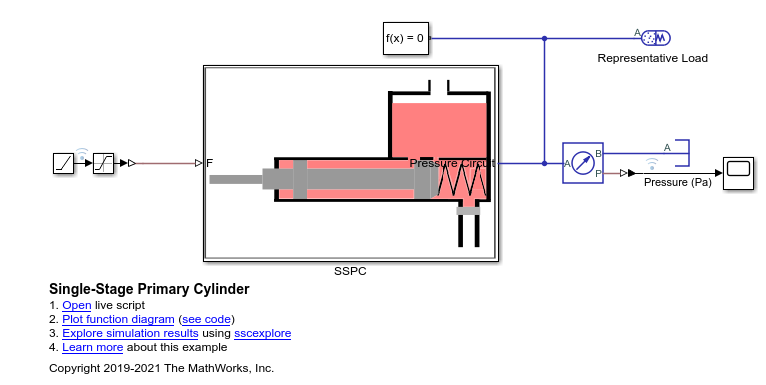

It is important to test the system with the correct load. In the test model, loading is done on the single-stage primary cylinder using spring-based accumulator. Setting up correct parameters in the accumulator is important. From the datasheet it is known what should be the stroke values for circuits. 

## Load circuit parameters

sspc.vol = sspc.v2M-sspc.v2D-sspc.aPist*sspc.deadzone;   % (m^3) Fluid chamber capacity for pressure circuit 
sspc.loadP = sspc.circuitP(3);                           % (Pa) Pressure at full capacity for pressure circuit 

## Simulation

The model generates push rod force versus pressure plots plots for selected manufacturer designs. The applied push rod force to the single-stage primary cylinder is ramped at 25 N/sec in the simulation.

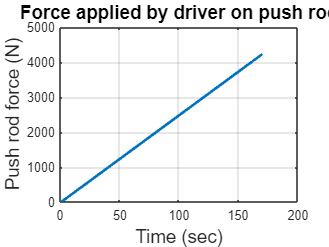

 simT = (sspc.pushRodF(3)/25)+10; % Simulation time
 sim('sscfluids_clutch_ss_primary_cyl.slx',simT)
 
% Plotting output from Simscape(TM) single-stage primary cylinder model and comparing
% with datasheet functional specification

figure
i1 = plot(logsout_sscfluids_clutch_ss_primary_cyl{1}.Values.Time,...
    logsout_sscfluids_clutch_ss_primary_cyl{2}.Values.Data);
i2 = xlabel('Time (sec)');
i3 = ylabel('Push rod force (N)');
i4 = title('Force applied by driver on push rod');
i1.LineWidth = 2;
i2.FontSize = 14;
i3.FontSize = 14;
i4.FontSize = 14;
grid on

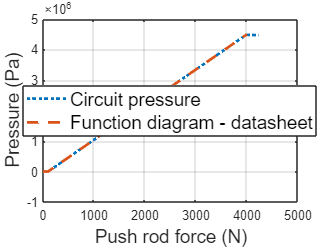


figure
p5 = plot(logsout_sscfluids_clutch_ss_primary_cyl{2}.Values.Data,logsout_sscfluids_clutch_ss_primary_cyl{1}.Values.Data,...
    ':',sspc.pushRodF,sspc.circuitP,'--');
p6 = legend('Circuit pressure','Function diagram - datasheet','location','best');
grid on
p5(1).LineWidth = 2;
p5(2).LineWidth = 2;
p7 = xlabel('Push rod force (N)');
p8 = ylabel('Pressure (Pa)');
p6.FontSize = 14;
p7.FontSize = 14;
p8.FontSize = 14;


clear i1 i2 i3 i4 p1 p2 p3 p4 p5 p6 p7 p8